dane = audioDatastore("dane\","IncludeSubfolders", true, 'LabelSource','foldernames')

dane =   audioDatastore with properties:

                       Files: {
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00000.wav';
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00001.wav';
                              ' ...\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00002.wav'
                               ... and 1401 more
                              }
                     Folders: {
                              'C:\Users\ja\MATLAB\Projects\BayesMusicClassification\dane'
                              }
                      Labels: [blues; blues; blues ... and 1401 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


[daneTrain, daneTest] = splitEachLabel(dane,0.8);
[x,xinfo] = read(daneTrain);
xinfo

xinfo = struct with fields:
    SampleRate: 22050
      FileName: 'C:\Users\ja\MATLAB\Projects\BayesMusicClassification\dane\blues\blues.00000.wav'
         Label: blues


%sound(x,xinfo.SampleRate)


%%

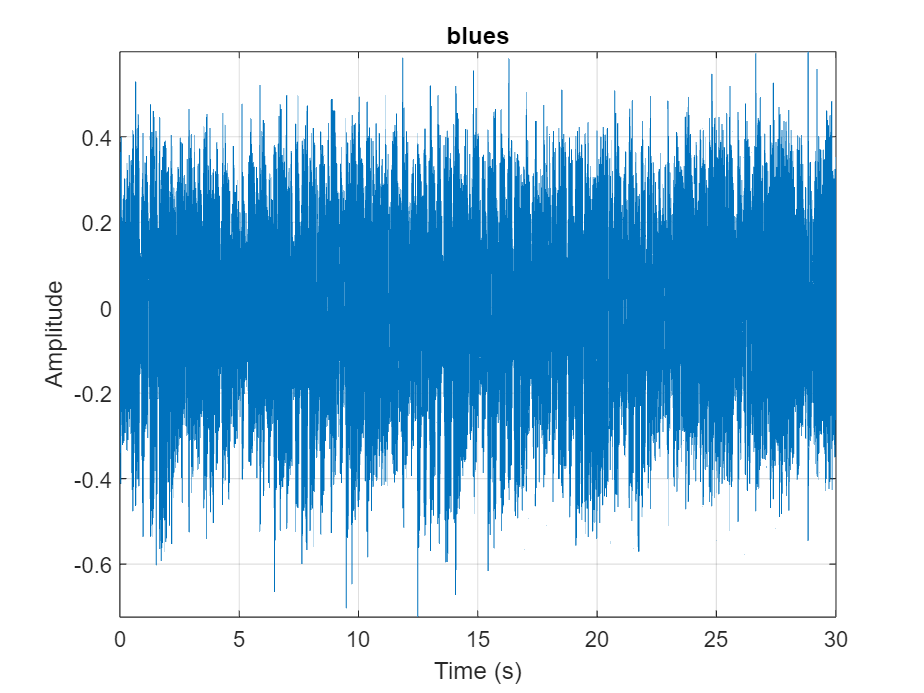


t = (0:numel(x)-1)/xinfo.SampleRate;
figure
plot(t,x)
title(xinfo.Label)
grid on
axis tight
ylabel("Amplitude")
xlabel("Time (s)")

fs = xinfo.SampleRate;
% Create and set up an audioFeatureExtractor object

%{
extractor = audioFeatureExtractor("SampleRate",xinfo.SampleRate, ...
    "linearSpectrum",false,"melSpectrum",true, ...
    "mfcc",true,"mfccDelta",true, ...
    "mfccDeltaDelta",true,"spectralCentroid",true, ...
    "spectralCrest",false,"spectralFlatness",false, ...
    "spectralFlux",false,"spectralSkewness",false, ...
    "spectralSlope",false,"pitch",false, ...
    "harmonicRatio",true,"zerocrossrate",true, ...
    "shortTimeEnergy",true);
%}

% Create and set up an audioFeatureExtractor object
extractor = audioFeatureExtractor("SampleRate",fs, ...
    "Window",hamming(512,"periodic"), ...
    "OverlapLength",round(512*0.25), ...
    "melSpectrum",true,"mfcc",true, ...
    "mfccDelta",true,"mfccDeltaDelta",true, ...
    "gtcc",true,"gtccDelta",true, ...
    "spectralCentroid",true,"harmonicRatio",true, ...
    "zerocrossrate",true,"shortTimeEnergy",true);
setExtractorParameters(extractor,"mfcc","NumCoeffs",20);

% Extract features from audio data
features = extract(extractor,x);
outputMap = info(extractor)

outputMap = struct with fields:
         melSpectrum: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32]
                mfcc: [33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52]
           mfccDelta: [53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72]
      mfccDeltaDelta: [73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89 90 91 92]
                gtcc: [93 94 95 96 97 98 99 100 101 102 103 104 105]
           gtccDelta: [106 107 108 109 110 111 112 113 114 115 116 117 118]
    spectralCentroid: 119
       harmonicRatio: 120
       zerocrossrate: 121
     shortTimeEnergy: 122


%windowSize = 1024;
%windowOverlap = windowSize * 0.5;
%extractor = audioFeatureExtractor(SampleRate=xinfo.SampleRate, ...
%    Window=hanning(windowSize,"periodic"), ...
%    OverlapLength=windowOverlap)

%in = info(extractor,"all");
%featureSwitches = fields(in);
%cellfun(@(x)extractor.set(x,true),featureSwitches)


featureMatrix = extract(extractor,x);
[numWindows,numFeatures] = size(featureMatrix)

numWindows = 1723

numFeatures = 122

%features = extract(extractor,x)
%plot(features)

pFlag = ~isempty(ver("parallel"));
daneTrainT = transform(daneTrain,@(x){extract(extractor,x)})

daneTrainT =   TransformedDatastore with properties:

      UnderlyingDatastores: {audioDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
                Transforms: {@(x){extract(extractor,x)}}
               IncludeInfo: 0


features = readall(daneTrainT,UseParallel=pFlag)

features = 1123×1 cell array
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}
    {1723×122 double}


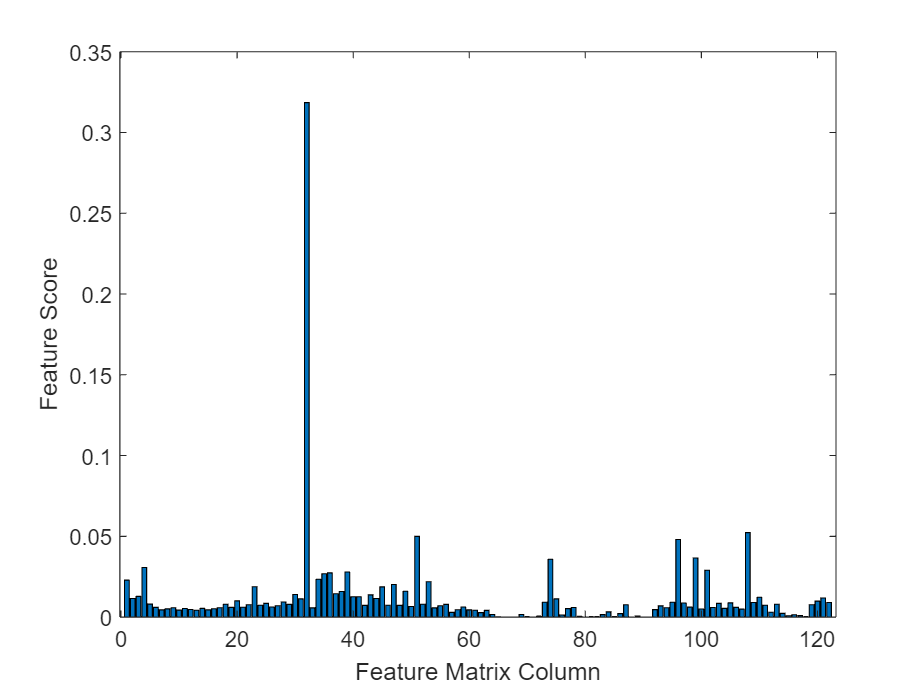


N = cellfun(@(x)size(x,1),features);
T = repelem(daneTrain.Labels,N);
X = cat(1,features{:});
rng("default") % for reproducibility
[featureSelectionIdx,featureSelectionScores] = fscmrmr(X,T);
figure
bar(featureSelectionScores)
ylabel("Feature Score")
xlabel("Feature Matrix Column")

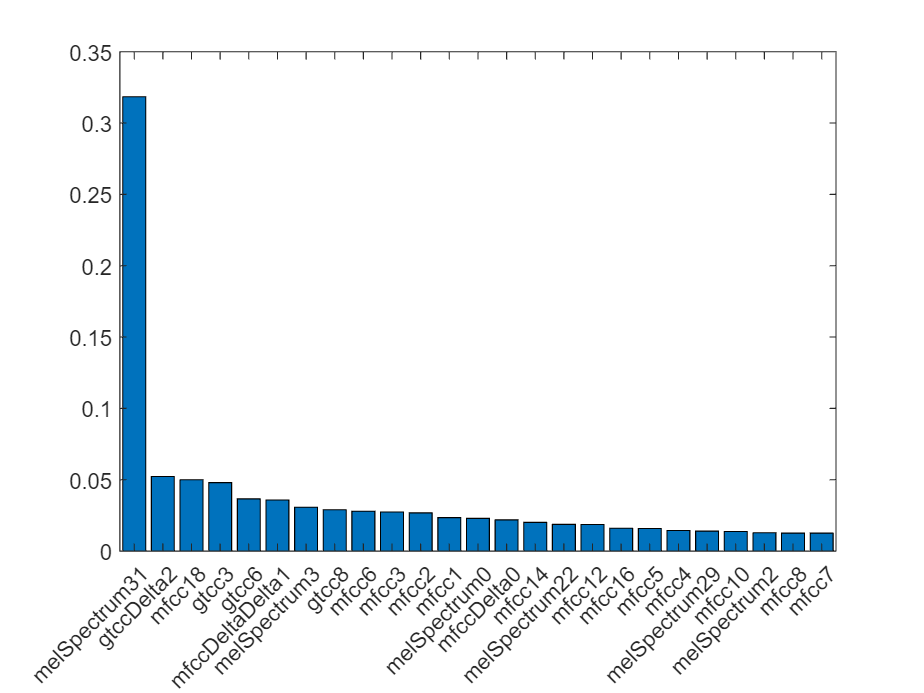


featurenames = uniqueFeatureName(outputMap);

featurenamesSorted = featurenames(featureSelectionIdx);
figure
bar(reordercats(categorical(featurenames),featurenamesSorted),featureSelectionScores)
xlim([featurenamesSorted(1),featurenamesSorted(25)])

selectedFeatureIndex = featureSelectionIdx(1:20);

Mdl = fitcnb(X(:,selectedFeatureIndex),T)

Mdl =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [blues    classical    country    disco    hiphop    jazz    metal    pop    reggae    rock]
            ScoreTransform: 'none'
           NumObservations: 1935704
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {10×20 cell}


  Properties, Methods


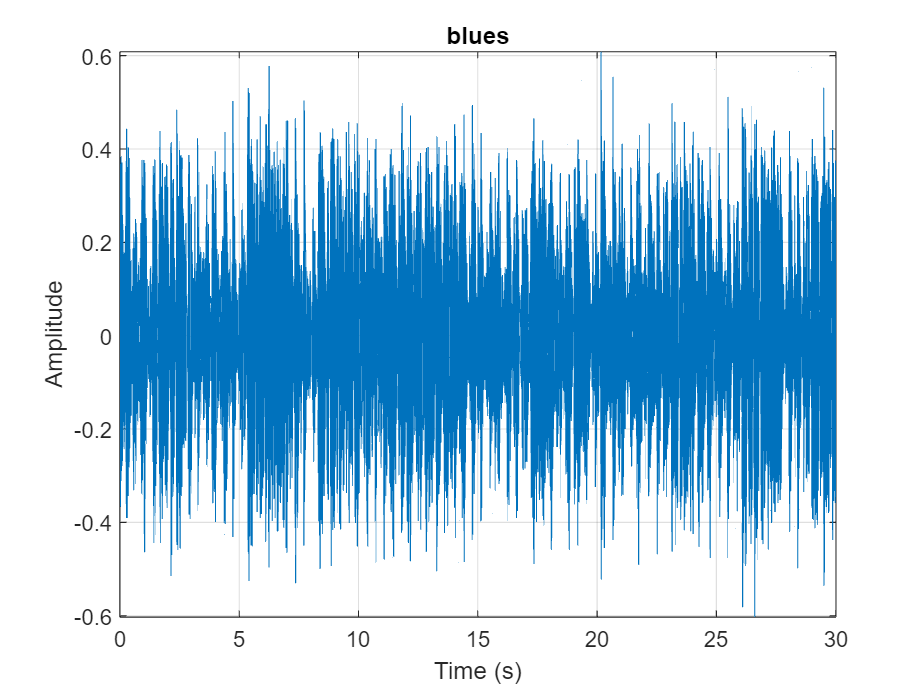

[x,xInfo] = read(daneTest);
%sound(x,xInfo.SampleRate)

t = (0:numel(x)-1)/xInfo.SampleRate;
figure
plot(t,x)
title(xInfo.Label)
grid on
axis tight
ylabel("Amplitude")
xlabel("Time (s)")

yPerWindow = extract(extractor,x);
t = predict(Mdl,yPerWindow(:,selectedFeatureIndex));
trueLabel = categorical(xInfo.Label)

trueLabel = categorical
     blues 


predictionsPerWindow = categorical(t')

predictionsPerWindow = 1×1723 categorical array
  Columns 1 through 834

     blues      hiphop      hiphop      hiphop      hiphop      hiphop      hiphop      classical      classical      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      metal      jazz      jazz      classical      jazz      jazz      blues      blues      classical      country      blues      blues      classical      blues      classical      classical      classical      blues      blues      blues      blues      blues      blues      blues      classical      blues      blues      blues      classical      blues      classical      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      blues      classical      classical      classical      blues      blues      blues      blues      blue

prediction = mode(predictionsPerWindow)

prediction = categorical
     blues 


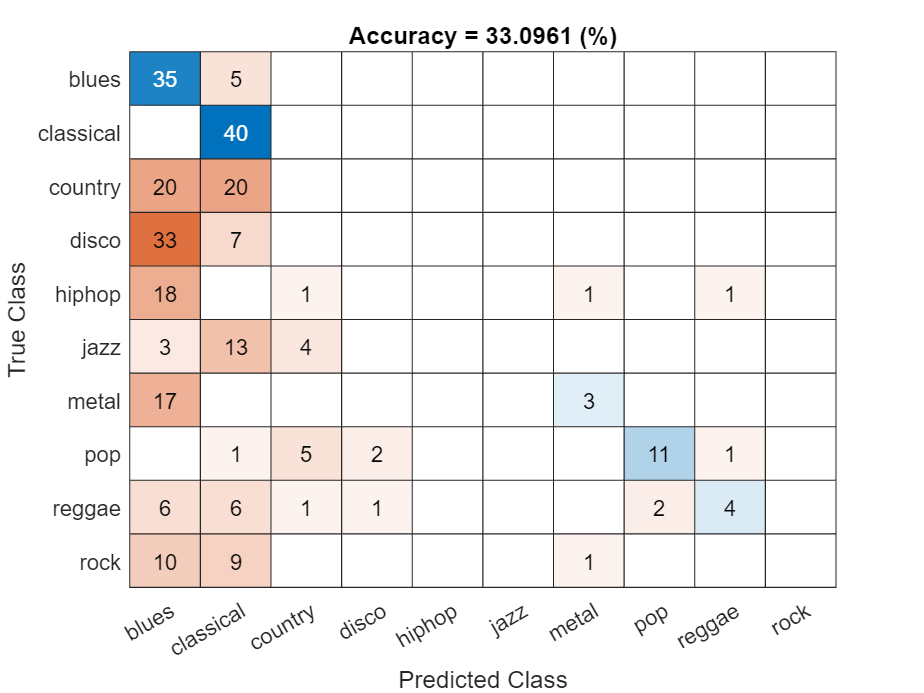

Tfile = categorical(daneTest.Labels);
daneTestT = transform(daneTest,@(x)extract(extractor,x));
daneTestTT = transform(daneTestT,@(x)mode(categorical(predict(Mdl,x(:,selectedFeatureIndex)))));
Y = readall(daneTestTT);
figure
confusionchart(Tfile,Y,Title="Accuracy = " + 100*mean(Tfile==Y) + " (%)")